clear

data1 = readmatrix('SegDens_15new.txt');
data2 = readmatrix('SegDens_20new.txt');
data3 = readmatrix('SegDens_25new.txt'); 
data4 = readmatrix('SegDens_5new.txt');
% data5 = readmatrix('NormSegDens_40new.txt');

x = data1(:,1);
y1 = data1(:, 2);
y2 = data2(:,2);
y3 = data3(:,2);
y4 = data4(:,2);
% y5 = data5(:,2);

avg = zeros(256,1);
for i = 1:256
    avg(i) = y1(i) + y2(i) + y3(i) + y4(i);
    avg(i) = avg(i)/4;
end

X = linspace(0,1,256)';
integral_approx = trapz(X,y1)

integral_approx = 0.9992

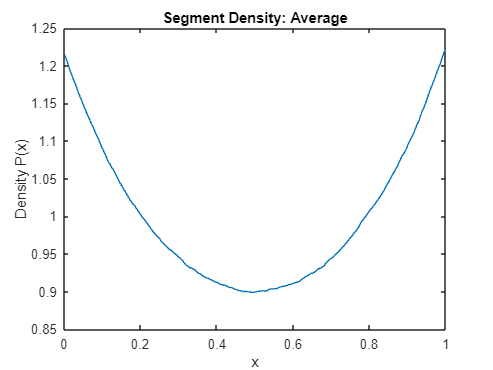


% plot(x,y1,'.',LineWidth=2);
% hold on; 
% plot(x,y2,'.',LineWidth=2);
% plot(x,y3,'.',LineWidth=2);
% plot(x,y4,'.',LineWidth=2);
% plot(x,y5,'.',LineWidth=2);
plot(x,avg)
xlabel('x');
ylabel('Density P(x)');
title('Segment Density: Average');

%legend('15', '20', '25','5');
% ylim([5*10^-3,8*10^-3]);
%hold off; 


## Fit the average


[k, min_idx] = min(avg);
h = x(min_idx);

pol = polyfit(x,avg,2);
a = pol(1);
X = ['For the fit a(x-h)^2 + k, a = ', num2str(a), ' and the vertex is (',num2str(h),', ',num2str(k),')'];
disp(X);

For the fit a(x-h)^2 + k, a = 1.2496 and the vertex is (0.49414, 0.8987)


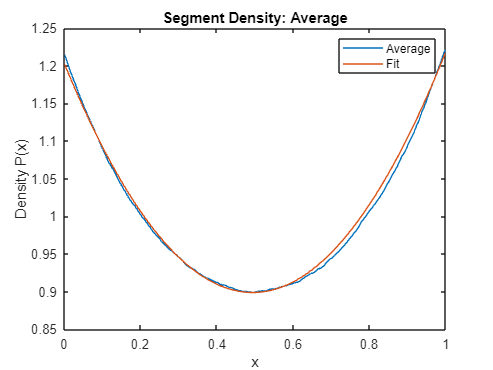


hold on;
plot(x,a.*(x-h).^2 + k)
legend('Average','Fit')
hold off;